# 1) Estimation of nominal ballistic properties of solid propellant

clc
clear
close all

% BARIA Bates-motor

% Grain
% Geometric properties
wt = 30; % web thickness [mm]                            % VERIFIED
L0 = 290; % [mm]                                         % VERIFIED
Ri0 = 50; % [mm]                                         % VERIFIED
Re0 = Ri0 + wt; % [mm]                                   % VERIFIED
A_t = pi.*[28.80,25.26,21.81].^2 ./4 % [mm^2]            % VERIFIED

A_t =   651.4407  501.1371  373.5951



% initial total grain volume
V = pi*(Re0^2 - Ri0^2)*L0           % [mm^3]             % VERIFIED

V = 3.5531e+06


% Mass Properties: OX, FU, BI
mperc_vec = [0.68, 0.18, 0.14];                          % VERIFIED
rho_vec   = [1950, 2700, 920]*1e-9; % [kg/mm^3]          % VERIFIED

% average propellant density                             
rho_av = 1/sum(mperc_vec./rho_vec)  % [kg/mm^3]           

rho_av = 1.7619e-06

M_tot = rho_av*V                    % [kg]

M_tot = 6.2604

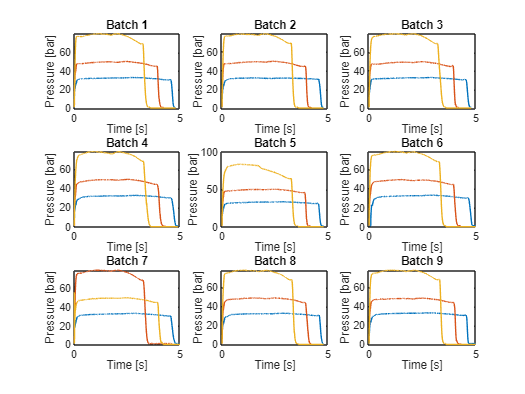

% Experimental data loading and plotting of pressure traces

% 9 batches with 3 motor firings each @ LP, MP, HP
data = load('tracesbar1.mat');
batch = fieldnames(data);   % names of batches fields of the struct

% PLOT 3 pressure curves for each of the 9 beatches firings tests
figure;

for i = 1:9
    
    p_mat_i = data.(batch{i}); % pressures of i-th batch
    
    p_L_i = p_mat_i(:, 1); % LP [bar]
    p_M_i = p_mat_i(:, 2); % MP [bar]
    p_H_i = p_mat_i(:, 3); % HP [bar]

    % time vector: sampling frequency f = 1 kHz, so sampling time dt = 0.001 s = 1ms
    N_t_i = length(p_L_i);
    time_vec_i = 0 : 0.001 : (N_t_i - 1)*0.001;

    % subplot 3x3
    subplot(3,3,i)
    plot(time_vec_i, p_L_i); hold on;
    plot(time_vec_i, p_M_i);
    plot(time_vec_i, p_H_i);

    title(['Batch ', num2str(i)])
    xlabel('Time [s]')
    ylabel('Pressure [bar]')
    
end


% PLOT a single  specific batch
plotSpecificBatch= false

plotSpecificBatch = logical
   0



if plotSpecificBatch
    i = 1;
    p_mat = data.(batch{i});
    N_t = length(p_mat(:, 1));
    time_vec = 0 : 0.001 : (N_t - 1)*0.001;

    figure;
    plot(time_vec, p_mat(:, 1)); hold on;
    plot(time_vec, p_mat(:, 2));
    plot(time_vec, p_mat(:, 3));

    title(['Batch', num2str(i)])
    xlabel('Time [s]')
    ylabel('Pressure [bar]')

    % Zoom on ignition transient (before steady-state transient)
    i = 1;
    p_mat = data.(batch{i});
    N_t = length(p_mat(:, 1));
    time_vec = 0 : 0.001 : (N_t - 1)*0.001;

    figure;
    plot(time_vec(1:40), p_mat(1:40, 1)); hold on;
    plot(time_vec(1:40), p_mat(1:40, 2));
    plot(time_vec(1:40), p_mat(1:40, 3));

    title(['Ignition transient - Batch', num2str(i)])
    xlabel('Time [s]')
    ylabel('Pressure [bar]')
end
i = 1;


REMARKS:

- BATES: indeed p almost constant ; the HP curve is **not** though, has a difference of 10  bar in the steady state, but you want to **model it as constant**.

- at the **end of the firing**: rump up due to **thermal wave** approaching the propellant end and the leftover of the propellant (few hundred of microns) has a Temperature that provockes rapid ignition of the whole remaining bulk; also due to boundary conditions that are different at the wall. And when you produce heterogeneous material, the BCs are important.

- **central point: small deflection** of p(t). Typical pb of these curves. In production you have the case; pour and plung the mandrel only after (for small motors)(only for big motors the mandrel is placed in the case since the beginning), but then this produce a flow and the particles and binder move differently. Half of the flow go downwards carried by viscosity, the external part rises. At the interface between these two motions, when this part burns we have a local stress with local altered composition and the resalt is this central point. So due to **production methodology**.

- **ignition transient** (zoom in): oscillating p(t), so **when can we consider ignition successfull in an engine?** In general, not only for solids, it is defined when we have the **final monotonic rump **up towards steady (steady state transition). So when it stops oscillating. Ignition time t_I is to be located after this ignition transient.

For this last problem: convention used for us is **BC methodology**:

### **BC methodology**

4 points are identified in a pressure trace:

1) p_max

2) A,D: t_a to t_d : action time (sth is happening in the engine)

3) B,C, t_b to t_c: burning time

HOW ARE THEY DEFINED?

1 ) SRM ACTION [A-D] (to exlude igniter behaviour and last part (chamber deflation))

- compute p_max

- compute t_a, t_d at with p(t) = 5%p_max for the last time before steady state transient and first time after steady state, so look for it starting from p_max andando a sinistra o a destra -> identify action time and corresponding pressures : t_a at p = 1%p_max but use 5% because our measurements are noisy.

-  It's not a problem as long as we stay consistent to your own methodoloy. But then do not compare r_b etc. (will be different) with someone who used a different methodology.

- reference pressure:$\;p_{\textrm{ref}} =\frac{\int_{t_A }^{t_{D\;} } p\left(t\right)\;\textrm{dt}}{2*\left(t_D -t_A \right)}$, *half* of mean value of p(t) during action. Since p(t) is discretized, compute integral via numerical approach.

2) SRM BURNING [B-C] (regression is uniform)

- t_B and t_C are the first and last time p(t) crosses p_ref found above. Effective burning time.

- Compute: $r_{b\;} =\frac{\Delta x=\textrm{web}}{t_{c\;} -t_{b\;} }\;\;\;,p_{\textrm{eff}\;} =\frac{\int \left(\textrm{from}\;t_B \;\textrm{to}\;t_C \right)\;p\;\textrm{dt}}{t_C -t_B }\;$. Where p_eff is what our model assumes as constant pressure during steady state behaviour.

In this way we only consider for rb the steady state behaviour, and we can use this rb to compute parameters of Vieille law, which is a steady-state law.


% This is for a SINGLE rocket engine, we have 9 batches * 3 motors per each
% batch = 27 motors to do this for.

% PROBLEMS solved: 
% point A tries to cancel igniter transient

% point B and C consider only steady state. At C we consider all propellant
% consumed,this is why for rb we use tC-tB not tD - tC.

% after C you have residuals from combustion and chamber deflation, and you
% eclude that behaviour from your analysis

% -> consider only steady state like this
% -> so you can gather data for Vieille Law, which has steady state
% assumption.


% Take a curve; identify p_max, but note that p_max maight be from the
% transient! 
%  - So first look at all 27 curves and try to write an algorithm
% to select the right p_max
% - also, identify 1 macroscopic error that is present

**Error**: pressures (LP,MP,HP) of batch 7 are catalogued wrong, maybe

some automatic process that identifies HP said it was HP because p_max was thought as the one of the igniter. A noi non cambia niente che siano catalogate sbagliate per quello che di fatto dobbiamo fare. Le 27 curve vengono tutte usate allo stesso modo, indipendentemente se LP, MP, o HP.

REMARK: zoom in batch 7 ignition transient:

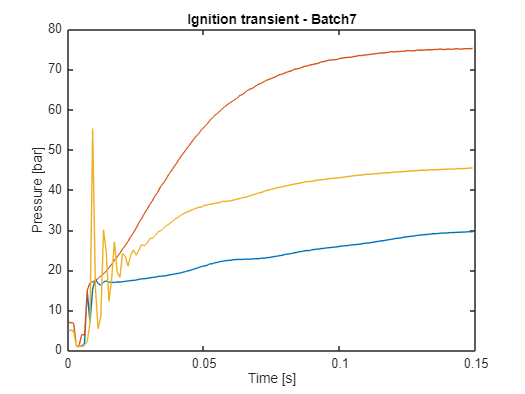

    % Zoom on batch 7 ignition transient (before steady-state transient)
    i = 7;
    p_mat = data.(batch{i});
    N_t = length(p_mat(:, 1));
    time_vec = 0 : 0.001 : (N_t - 1)*0.001;

    figure;
    plot(time_vec(1:150), p_mat(1:150, 1)); hold on;
    plot(time_vec(1:150), p_mat(1:150, 2));
    plot(time_vec(1:150), p_mat(1:150, 3));

    title(['Ignition transient - Batch', num2str(i)])
    xlabel('Time [s]')
    ylabel('Pressure [bar]')

-> Quindi per identificare p_max per ciascuna curva fai un algoritmo che stia attento a questo e selezioni il p_max non tra i valori del transient.

## **Find (p_eff, r_b) for each batch and c***

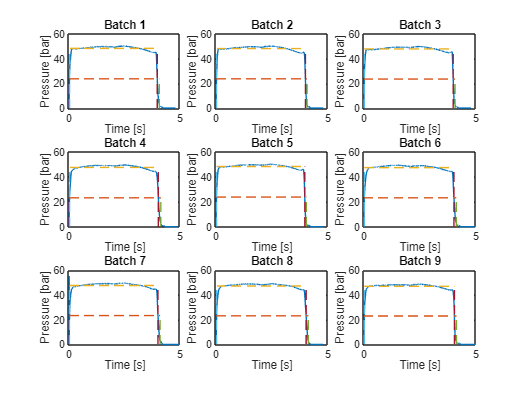


% 1) ACTION TIME INTERVAL

% Identify p_max, 
% NOTE: that shall not be in the transient, so if it is found in the
% first 200 points (non mi piace, non generale, you could also a moving mean,
% but anyways you must justify your methodology, not do a too general thing, you
% are only interesed in these batches! It must be like a technical report from
% a technician to another technician
% the 5% threshold should be found starting search from central p_max, not
% from the start, otherwise you may find it in the oscillating transient
% before.
%  - find p_max

p_eff_vec = zeros(9,3);
rb_vec  = zeros(9,3);
tB_vec = zeros(9,3);
tC_vec = zeros(9,3);
c_vec  = zeros(27,1);

figure;

for i = 1 : 9 % batches
    for j = 1 : 3 % 3 motors for each batch

    p_mat_i = data.(batch{i}); % pressures of i-th batch

    if i == 7 
        if j == 2
        p = p_mat_i(:, 3);
        elseif j == 3
        p = p_mat_i(:,2);
        else
        p = p_mat_i(:, 1);
        end
    else
      p = p_mat_i(:, j); % [bar]
    end

    % time vector: 
    N_t = length(p);
    time_vec = 0 : 0.001 : (N_t - 1)*0.001;
    [p_max, idx_max] = max([zeros(199,1);p(200:end)]);
    p_max;

    % find action interval times tA, tD:

    % tA:
    p_i = inf;
    k = 0;
    while p_i > 0.05*p_max
         k = k+1;
         p_i = p(idx_max - k);
    end
    idxA = idx_max - k;
    tA = time_vec(idxA);

    % tD:
    p_i = inf;
    k = 0;
    while p_i > 0.05*p_max
         k = k+1;
         p_i = p(idx_max + k);
    end
    idxD = idx_max + k;
    tD = time_vec(idxD);


% Integration p(t) in [tA, tD]
intg = trapz(time_vec(idxA:idxD), p(idxA:idxD));
p_mean = intg/(tD-tA);
p_ref = p_mean/2;

% 2) BURNING TIME INTERVAL
 % similar to above
 % find burning interval times tB, tC:

    % tB:
    p_i = inf;
    k = 0;
    while p_i > p_ref
         k = k+1;
         p_i = p(idx_max - k);
    end
    idxB = idx_max - k;
    tB = time_vec(idxB);
    tB_vec(i,j)= tB;

    % tC:
    p_i = inf;
    k = 0;
    while p_i > p_ref
         k = k+1;
         p_i = p(idx_max + k);
    end
    idxC = idx_max + k;
    tC = time_vec(idxC);
    tC_vec(i,j)= tC;

% Integral in [tB, tC]
intg = trapz(time_vec(idxB:idxC), p(idxB:idxC));
p_mean = intg/(tC-tB);
% p_eff is the mean of p(t) in the burning time interval
p_eff = p_mean;

% burning rate:
rb = wt/(tC-tB);

p_eff_vec (i,j) = p_eff;
rb_vec (i,j) = rb;

% Computation of c*
% Integral in [tB, tC]
c = intg*0.1*A_t(j)/M_tot; % m/s ; 
c_vec(j+(i-1)*3) = c;

% subplot 3x9
    if j == 2  % only for the MP, per non sovrapporre troppe linee. Se li vuoi vedere tutti 27, togli questo if
    subplot(3,3,i)
    plot(time_vec, p); hold on;
    plot([tA,tD], ones(1,2)* p_ref,'--');
    plot([tB,tC], ones(1,2)* p_eff,'--');
    plot(tA*ones(2,1), [0,p_ref],'--');
    plot(tD*ones(2,1), [0,p_ref],'--');
    plot(tB*ones(2,1), [0,p_eff],'--');
    plot(tC*ones(2,1), [0,p_eff],'--');

    title(['Batch ', num2str(i)])
    xlabel('Time [s]')
    ylabel('Pressure [bar]')
    end

    end

    hold off;
    
end



% mean combustion intervals: (mean along columns)
tB_mean = mean(tB_vec) % LP,MP,HP

tB_mean =     0.0258    0.0233    0.0297


tC_mean = mean(tC_vec) % LP,MP,HP

tC_mean =     4.6601    4.0120    3.3514



rb_vec;
rb_LP = mean(rb_vec(:,1))

rb_LP = 6.4737

rb_MP = mean(rb_vec(:,2)); % 7.6888 mm/s
rb_HP = mean(rb_vec(:,3))

rb_HP = 9.0318


p_eff_vec

p_eff_vec =    31.6085   48.2014   76.5411
   31.3917   48.0201   76.2432
   31.6129   47.7393   76.0650
   31.2116   47.3170   74.7587
   31.8831   48.0794   75.8042
   31.3596   47.1796   74.9387
   31.5147   47.6152   75.4827
   31.5195   47.2099   75.0334
   31.9192   46.9672   74.8840


p_eff_LP = mean(p_eff_vec(:,1))

p_eff_LP = 31.5579

p_eff_MP = mean(p_eff_vec(:,2))

p_eff_MP = 47.5921

p_eff_HP = mean(p_eff_vec(:,3))

p_eff_HP = 75.5279


% deltax = 30 mm;

% OBS.: environmental pressure 1 bar : is the propellant sensitive from the
% relative pressure or also to the pressure of the environment? The
% propellant senses the static local pressure, so if you have 70 bar
% absolute pressure, the Vieille low and whole balistic depends on it. If
% you have 69 relative pressure wrt the environment, also add 1 bar of the 
% environment to compute the ballistics, Vieille, etc. Kinetics of ballistic is related
% to the static pressure, so absolute, also the 1 bar of the environment.
% (?)

% rb = 7.591 mm/s ok for MP, ok for solid propellants

% solutions:
% LP : 6 - 6.5 mm/s , 30 - 40 bar
% MP : 7.5 mm/s     , 40 - 50 bar
% HP : 8.5 - 9.5 m/s, 70 - 85 bar

p_val = [p_eff_vec(:,1); p_eff_vec(:,2); p_eff_vec(:,3)];
 
r_val = [rb_vec(:,1); rb_vec(:,2); rb_vec(:,3)];


% Performance of C.C.:
% experimental characteristic velocity:
% Under assumption that c is changing only negligibly wrt the pressure, we
% can average the entire dataset (assuming all variables for all batches to be indipendent and identically
% distributed (same history of production))

% Stima della Valor Medio
c = mean(c_vec)

c = 1.5128e+03

% 
Is = c/9.81

Is = 154.2084


% Stima Deviazione Standard (Deviazione std campionaria (Bessel))
Sigma_c = sqrt(1/(27-1) * sum((c_vec - c).^2)) % [m/s]

Sigma_c = 11.9357

## Vieille Law [steady-state hp] 

% considering it
% loglog, i can find a, n:
% log(r_b) = log(a) + n*log(p) 
%        X =   q    + m*Y

% do not rewrite all the theory, only document your brain process to show
% your boss how you did it. Only the results and short proof that these
% results make sense and show how you got them (your reasoning).

% solutions
a = 1.77 ; % mm/s / bar^n (attento se cambi udm va elevato alla n)
n = 0.38

n = 0.3800


% uncertaintes...
% sigma_a = 
% sigma_n = 
% Assuming all variables for all batches to be indipendent and identically
% distributed (same history of production), we can trace a regression line 
% using all 27 points together:

X = log(p_val);                                                        % conversione valori di pressione in scala logaritmica
N = length(p_val);                                                     % lunghezza vettore delle pressioni
Y = log(r_val);                                                        % conversione valori di rb in scala logaritmica

delta = N * sum(X.^2)-(sum(X))^2;                                   % denominatore per il calcolo di q e m
m = ( N*sum(X.*Y) - sum(X)*sum(Y) ) / delta; 
% Mean value of pressure exponent:
n = m;                                                              % dal passaggio sopra
q = ( sum(X.^2)*sum(Y) - sum(X)*sum(X.*Y)) / delta;                 % intercetta della retta Y = mX + q con m = n

Y_eval = m .* X + q;                                                % valori valutati tramite equazione della retta appena calcolata
sig = ( ( sum( ( Y - Y_eval ).^2) ) / (N-2) )^0.5;                  % scarto quadratico medio dei valori reali da quelli della retta

Inc_m = sig * (N/delta)^0.5                                         % incertezza del coeff "m" (che coincide con quella di "n")

Inc_m = 0.0027

% Estimation of Standard deviation of pre-exponential coefficient
Inc_n = Inc_m;     % m=n ->  Inc_n = Inc_m                                                  % dal passaggio sopra
Inc_q = sig * ( sum( X.^2 ) / delta )^0.5;                          % incertezza del coeff "q"

% Estimation of Mean value of pre-exponential coefficient
a = exp(q);                                                         % calcolo del valore "a"
a_new_up = a * exp(Inc_q);                                          % calcolo della parte superiore l'incertezza di "a"
a_new_down = a / exp(Inc_q);                                        % calcolo della parte inferiore per l'incertezza di "a"
% Estimation of Standard deviation of pre-exponential coefficient
Inc_a = ( a_new_up - a_new_down) / 2;                               % calcolo di "a"


M_Y = mean(Y);                                                      % calcolo della media di Y
dev_reg = sum ( (Y_eval - M_Y).^2 );                                % calcolo della devianza di regressione
dev_tot = sum ( (Y - M_Y).^2 );                                     % calcolo della devianza totale
R2 = dev_reg / dev_tot  % close to 1 -> data have strong linear dependance   % calcolo del coefficiente R^2

R2 = 0.9987


figure;
plot(log(p_val),log(r_val),'o'); hold on;
plot([min(log(p_val)),max(log(p_val))], polyval([n,log(a)],[min(log(p_val)),max(log(p_val))]));



# 2) Motor model

Second part

BARIA motor geometry

centrally perforated grain; combustion burns both radially and axially. Klemmung info is  $K\left(t\right)=\frac{A_{b\;\left(t\right)} }{A_t }$. You have different A_t for LP, MP, HP. 


$$p_c \left(t\right)={\left(\rho_{\textrm{prop}} K\left(t\right)\;{\textrm{ac}}^* \right)}^{\left(\frac{1}{1-n}\right)\;} \;$$


where $\rho_{\textrm{prop}} =\langle \rho \rangle$ computed before.

Implement an algorithm to plot p_c(t). You need to trace the regression of A_b(t). You can assume r_b axial and radial are the same. Vertex P moves horizontally and vertically with same r_b. When its coordinates are (0,0) it ends. 

OSS: in this way you are not modelling the ignition transient

Here you have the nominal burning time

At = 651.4407

Sigmac_star = 1.1936e+04

z0 = 0

idx_C = 467009

tC = 4.6701

Case 1 : p0_i = 29.937986, t = 4.670080 


At = 501.1371

Sigmac_star = 1.1936e+04

z0 = 0

idx_C = 397083

tC = 3.9708

Case 2 : p0_i = 45.770397, t = 3.970820 


At = 373.5951

Sigmac_star = 1.1936e+04

z0 = 0

idx_C = 331135

tC = 3.3113

Case 3 : p0_i = 73.623532, t = 3.311340 


close all; grid on;
figure(1); hold on; xlabel('t [s]'); ylabel('z [burned width] [mm]');

figure(2); hold on; xlabel('t [s]'); ylabel('r_b [mm/s]');
figure(3); hold on; xlabel('t [s]'); ylabel('P_c [bar]');
figure(4); hold on; xlabel('t [s]'); ylabel('A_b [mm^2]');
% --- Colori per LP, MP, HP ---
colors_real  = [0.7 0.7 1;   % blu pastello LP
                0.7 1 0.7;   % verde pastello MP
                1 0.7 0.7];  % rosso pastello HP
colors_model = colors_real * 0.9; colors_model(colors_model>1) = 1; % più saturi

labels = {'LP','MP','HP'};


for j = 1 : 3   % LP, MP, HP

At = A_t(j) % MP case;
% a   % mm/s / bar^n
% rho_av  %[kg/mm^3]
% At  % mm^2
% n  % [-]
% Ri0       % [mm]
% Re0       % [mm]
c_star = c*1000; %mm/s
Sigmac_star = Sigma_c*1000
% k = 0.3
% c_star = c_star + k*Sigmac_star
% CONSERVATION OF MASS ('Pressure Equation') [hp: ...]
% dz(t) = rb(t), burning rate, = derivative of z burned width
dz = @(Ab) a*(a*rho_av*c_star*Ab./At / 100).^(n/(1-n)); % dz = p^n ; /100 to have all mm -> m and then Pa -> bar
% VIEILLE LAW [hp: ...]
% rb = @(p) a*p.^n;
% GRAIN GEOMETRY [hp: ...]
% z = erosion width (integral of rb)
%Ab = @(z) 2*pi*(Ri0 + z).*(L0-z) + pi*(Re0^2 - (Ri0 + z).^2);
Ab = @(z) 2*pi*(Ri0 + z).*(L0 - 2*z) + 2*pi*(Re0^2 - (Ri0 + z).^2);
% Regression on both sides. At final instant, Ab laterale deve passare a 0
% istantaneamente, mentre un istante prima non lo è in generale
% perchè, sebbene L regredisca, radialmente regredisce prima quindi alla fine passo
% da una superficie cilindra di lunghezza <L a 0. Questo però renderebbe Ab non differenziabile in t_end
% of burn. Quindi ciò viene aggiustato dopo, sottraendo A_lat del casing
% cilindrico alla Ab al tempo finale di burning tb trovato come tempo al
% quale z = w. Infatti Ab avrà da A_lat a 0 istantaneamente in t = tb. Di
% fatto imporremo Ab = 0 alla fine.


% I.C. for z(t):
% Solve for z:
z0 = 0   % burned width = 0 initially
t0 = 0; % [s]
tf = 6; % [s]
tspan = t0:0.00001:tf;
dzt = @(t,z) dz(Ab(z));
options = odeset('RelTol',1e-9,'AbsTol',1e-9); % tolleranze più basse = soluzione più precisa
[t, z_sol] = ode45(dzt, tspan, z0, options);
z_sol = real(z_sol); % burned width. Its derivative is rb(t) = dz :


% Find instant of end of burning
[~, idx_C] = min(abs(z_sol - wt))
 % first value for which it happens: time tC (end of burning interval)
tC = t(idx_C)
tB = 0;
t_BC = t(1:idx_C);
z_sol = z_sol(1:idx_C);
Ab_sol = Ab(z_sol);  % [mm^2/s]
Ab_sol = [Ab_sol(1:end-1); 0];
rb = dz(Ab_sol);
rb = real(rb);
% Vieille:
p_sol = (rb./a).^(1/n);

% figure;
% plot(t_BC,z_sol);
% xlabel('t [s]'); ylabel('z [burned width] [bar]');
% 
% figure;
% plot(t_BC,rb);
% xlabel('t [s]'); ylabel('r_{b} [mm/s]');
% 
% figure;
% plot([0; t_BC ; t(end)],[0;p_sol;0]);
% xlabel('t [s]'); ylabel('P_{c} [bar]');

% figure;
% plot(t_BC , Ab_sol);
% xlabel('t [s]'); ylabel('A_{b} [mm^2/s]');

fprintf('Case %d : p0_i = %f, t = %f \n', j, p_sol(1), t_BC(end));
    
    figure(1); plot(t_BC, z_sol, '-', 'Color', colors_model(j,:), 'LineWidth',1.5);
    figure(2); plot(t_BC, rb, '-', 'Color', colors_model(j,:), 'LineWidth',1.5);
    figure(3); plot(t_BC(1:end-1), p_sol(1:end-1), '-', 'Color', colors_model(j,:), 'LineWidth',1.5);
    figure(4); plot(t_BC, Ab_sol, '-', 'Color', colors_model(j,:), 'LineWidth',1.5);

    
end


% doesnt model transients
% explain Ab discontinuity in tC



%% --- Dati reali batch 5 ---
i = 5; 
p_mat_i = data.(batch{i}); 
p_L_i = p_mat_i(:,1); p_M_i = p_mat_i(:,2); p_H_i = p_mat_i(:,3);

N_t_i = length(p_L_i);
time_vec_i = 0:0.001:(N_t_i-1)*0.001;

% indici burning
idxB = [find(time_vec_i >= tB_vec(i,1),1,'first'), ...
        find(time_vec_i >= tB_vec(i,2),1,'first'), ...
        find(time_vec_i >= tB_vec(i,3),1,'first')];
idxC = [find(time_vec_i <= tC_vec(i,1),1,'last'), ...
        find(time_vec_i <= tC_vec(i,2),1,'last'), ...
        find(time_vec_i <= tC_vec(i,3),1,'last')];

figure(3); hold on;

% LP
plot(time_vec_i, p_L_i, '--', 'Color', colors_real(1,:), 'LineWidth',0.8);
plot(time_vec_i(idxB(1):idxC(1)), p_L_i(idxB(1):idxC(1)), '-', 'Color', colors_real(1,:), 'LineWidth',2);

% MP
plot(time_vec_i, p_M_i, '--', 'Color', colors_real(2,:), 'LineWidth',0.8);
plot(time_vec_i(idxB(2):idxC(2)), p_M_i(idxB(2):idxC(2)), '-', 'Color', colors_real(2,:), 'LineWidth',2);

% HP
plot(time_vec_i, p_H_i, '--', 'Color', colors_real(3,:), 'LineWidth',0.8);
plot(time_vec_i(idxB(3):idxC(3)), p_H_i(idxB(3):idxC(3)), '-', 'Color', colors_real(3,:), 'LineWidth',2);

xlabel('Time [s]');
ylabel('Pressure [bar]');
legend('LP model','MP model','HP model','LP real burn transients', 'LP real burn','MP real burn transients','MP real burn','HP real burn transients','HP real burn');
title('Confronto pressioni modello e reali');
grid on;





% Calculate the error as the difference in areas, proportional to c_star
% -> proportional to Is -> percentual error in performance estimation using
% this model
% Esempio: confronto del modello con il batch 5, per LP o MP o HP: ( lo
% stesso si può fare per ogni batch


$$\begin{array}{l}
I_{s_{\textrm{th}} } =\int_{t_{B_{\textrm{th}} } =0}^{t_{C_{\textrm{th}} } } {p\left(t\right)}_{\textrm{th}\;} \frac{A_{t\;} }{M_{\textrm{tot}\;} }\frac{\;1}{g_{0\;} }\\
{I_s }_{\exp } =\int_{{t_B }_{\exp } }^{t_{C_{\exp } } } \;{p\left(t\right)}_{\exp } \;\frac{A_t }{M_{\textrm{tot}} }\frac{\;1}{g_{0\;} }
\end{array}$$


so the ratio is  (to see if model is more performative than experimental/real with losses and other effectes that could also be beneficial):


$$\frac{I_{s_{\textrm{th}} } }{I_{\exp } }=\frac{\int_{t_{B_{\textrm{th}} } =0}^{t_{C_{\textrm{th}} } } {p\left(t\right)}_{\textrm{th}\;} }{\int_{{t_B }_{\exp } }^{t_{C_{\exp } } } \;{p\left(t\right)}_{\exp } }$$


Di fatto abbiamo c_vec, quindi calcoliamo c_star teorico del modello e facciamo il rapporto, e graficamente questo è il rapporto areolare:

c_vec_th = zeros(1,3);

for j = 1 : 3   % LP, MP, HP

At = A_t(j);
c_star = c*1000;
Sigmac_star = Sigma_c*1000
dz = @(Ab) a*(a*rho_av*c_star*Ab./At / 100).^(n/(1-n)); % dz = p^n ; /100 to have all mm -> m and then Pa -> bar
Ab = @(z) 2*pi*(Ri0 + z).*(L0 - 2*z) + 2*pi*(Re0^2 - (Ri0 + z).^2);
z0 = 0   % burned width = 0 initially
t0 = 0; % [s]
tf = 6; % [s]
tspan = t0:0.00001:tf;
dzt = @(t,z) dz(Ab(z));
options = odeset('RelTol',1e-9,'AbsTol',1e-9); % tolleranze più basse = soluzione più precisa
[t, z_sol] = ode45(dzt, tspan, z0, options);
z_sol = real(z_sol); % burned width. Its derivative is rb(t) = dz :


% Find instant of end of burning
[~, idx_C] = min(abs(z_sol - wt))
 % first value for which it happens: time tC (end of burning interval)
tC = t(idx_C)
tB = 0;
t_BC = t(1:idx_C);
z_sol = z_sol(1:idx_C);
Ab_sol = Ab(z_sol);  % [mm^2/s]
Ab_sol = [Ab_sol(1:end-1); 0];
rb = dz(Ab_sol);
rb = real(rb);
% Vieille:
p_sol = (rb./a).^(1/n);

c_vec_th(1,j) = trapz(t(1:idx_C), p_sol*10^5)*(A_t(j)*1e-6)/M_tot; % m/s
    
end

Sigmac_star = 1.1936e+04

z0 = 0

idx_C = 467009

tC = 4.6701

Sigmac_star = 1.1936e+04

z0 = 0

idx_C = 397083

tC = 3.9708

Sigmac_star = 1.1936e+04

z0 = 0

idx_C = 331135

tC = 3.3113

% efficiency
eta_vec = (ones(9,1)*c_vec_th)./(reshape(c_vec, 3, 9))'

eta_vec =     0.9945    0.9921    1.0076
    0.9983    0.9896    1.0069
    0.9963    0.9946    1.0108
    0.9940    0.9985    1.0140
    0.9910    0.9954    1.0125
    0.9935    0.9984    1.0107
    0.9944    0.9957    1.0110
    0.9932    0.9988    1.0100
    0.9916    0.9974    1.0108


mean(eta_vec)

ans =     0.9941    0.9956    1.0105


figure
plot(eta_vec(:,1)); hold on;
plot(eta_vec(:,2))
plot(eta_vec(:,3))

% HP is always overextimated, while LP is always underextimated  by the
% model wrt real case. MP is in between.



%  - concavità: dovuto a geometria cilindrica, come in fisica tecnica...
%  - solo crescente -> v. Slide Paravan ...
%  - confronto con uno di quello sperimentali (doesn't capture some effects...)
%  - VS usare Shapiro (v. suo paper ResearchGate)


# 3) ADDITIONAL/OPTIONAL TASK: Uncertaintes propagation in rocket motor

$\rho {\;}_{\textrm{prop}}$ can be computed

At fixed because ...

$A_b \left(t\right)$ changes at each t

$c^{*\;}$can be computed either from CEA (see theory) or from  the pressure tracks you have here!!! with:


$$c^* =\frac{\int \;P_0 \textrm{dt}}{M_{p\;} }A_t$$


So you can compute the engine efficiency 


$$I_s =\frac{c^{*\;} }{g}$$


You obtain 27 values of c*, and so c*_bar mean value and also $\sigma_{c*}$

Monte Carlo approach/campaign

- Select the uncertaintes you want to introduce, e.g. uncertaintes in a,n values. 

- Select what type of uncertaintes to introduce: epistemic (if you don't know something, e.g. you know that it is between 1 and 2 , probability is a const. same probability to have it in that range )or aleatory (e.g. due production of the motor). For the epistemic we can improve the uncertainty using statistical campains, while aleatory cannot be reduced! Aleatory is gaussian (because you have experiments, gaussian results, Shapiro Wilks etc.), the epistemic is a uniform probability model (because you don't have clues)

In our case a, n from 27 tests. our sigma a sigma n are uncertaintes from aleatory. So we model the uncertaintes as Errors of a and n as E_a ~ N(mu_a = a, sigma_a) (sigma_a computed before),

E_n ~ N(mu_n = n, sigma_n) 

In Monte carlo order is important, lest no convergence of the method.

You create the population of, e.g.  a[1:100],n[1:100] BEFORE the Monte Carlo Analysis. 

You run with a from a_1 to a_end and n1, then with a_2, etc. so all combinations (a_i,n_j)

But then you need to shuffle these couples, so the (a_i,n_j) are all shaffled.

Monitoring: [...]